# BallBot - 2D XY Model

clc; clear all

syms g m_b m_w m_r I_b I_w I_r ...
    R_b R_w l ...
    gamma eta lambda alpha m_t I_t ...
    x_1 x_2 T ...
    psi_r psi_dot_r

M = I_r + m_w*(R_b+R_w)^2*sin(alpha)^2 + I_w

$$M = I_{r}+I_{w}+m_{w}\,{\sin\left(\alpha \right)}^{2}\,{\left(R_{b}+R_{w}\right)}^{2}$$

C = 0;
G = 0;
Q = (-R_b/R_w)*T

$$Q = -\frac{R_{b}\,T}{R_{w}}$$

aux = simplify(inv(M)*(Q-C-G))

$$aux = -\frac{R_{b}\,T}{R_{w}\,\left(I_{r}+I_{w}+m_{w}\,{\sin\left(\alpha \right)}^{2}\,{\left(R_{b}+R_{w}\right)}^{2}\right)}$$

## Space - State For the X-Z Plane


$$x_1 = \psi_r \rightarrow Robot \, yaw \, angle$$



$$x_2 = \dot{\psi_r} \rightarrow Robot \, yaw \, rate$$



$$\left(\begin{array}{c} 
\dot{x_1} \\ 
\dot{x_2}
\end{array}\right) 
= \left(\begin{array}{c} 
x_2 \\ 
-\frac{R_b \,T}{R_w \,{\left(I_r + I_w + m_w \,{{\left(R_b +R_w \right)}}^2 \, \sin^2(\alpha)^\right)}}
\end{array} \right) $$


X_dot = [x_2; aux(1)];
A_sym = jacobian(X_dot, [x_1, x_2])

$$A\_sym = \left(\begin{array}{cc} 0 & 1\\ 0 & 0 \end{array}\right)$$

B_sym = jacobian(X_dot, T)

$$B\_sym = \left(\begin{array}{c} 0\\ -\frac{R_{b}}{R_{w}\,\left(I_{r}+I_{w}+m_{w}\,{\sin\left(\alpha \right)}^{2}\,{\left(R_{b}+R_{w}\right)}^{2}\right)} \end{array}\right)$$

# X-Y Physical Parameters

g_value = 9.81;                                                           % m/s^2


% %% BalBot V2
robot = struct( ...
    'm_w',      0.03873, ...  % kg
    'I_w',      1.96e-5, ...  % kg*m^2 (X-Z Plane Inertias)
    'I_r',      1.03e-2, ...  % kg*m^2 (X-Z Plane Inertias)
    'R_b',      0.12, ...     % m
    'R_w',      0.035, ...    % m
    'alpha',    deg2rad(45)); % deg      

x_1_value = 0; x_2_value = 0; T_value = 0;

A = double(subs(A_sym, [m_w, I_r, I_w, R_b, R_w, T, alpha], ...
        [robot.m_w, ...
         robot.I_r, ...
         robot.I_w, ...
         robot.R_b, ...
         robot.R_w, ...
         T_value, ...
         robot.alpha]))

A =      0     1
     0     0


B = double(subs(B_sym, [m_w, I_r, I_w, R_b, R_w, alpha], ...
        [robot.m_w, ...
         robot.I_r, ...
         robot.I_w, ...
         robot.R_b, ...
         robot.R_w, ...
         robot.alpha]))

B =          0
 -317.9064


eig(A)

ans =      0
     0


rank(ctrb(A, B))

ans = 2

rank(obsv(A, eye(2)))

ans = 2

sys = ss(A, B, eye(2), 0);
eig(sys)

ans =      0
     0


## Simulating the Dynamics of the System

out = sim("XYSim.slx", 10);
psi_r_ref = rad2deg((out.y.Data(:, 1)));
psi_r = rad2deg((out.y.Data(:, 2)));
psi_r_dot = rad2deg(out.y.Data(:, 3));
T = out.y.Data(:, 3);
data = [out.tout, psi_r_ref, psi_r, psi_r_dot, T];
save("step.mat", "data")

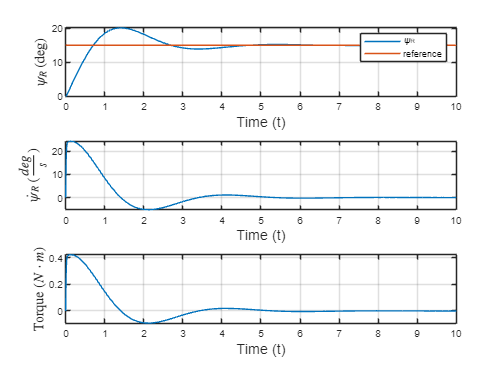

subplot(3, 1, 1);
plot(out.tout, psi_r, out.tout, psi_r_ref);
legend('\psi_R', 'reference')
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('$\psi_R$ (deg)', 'Interpreter', 'latex', 'FontSize', 12);

subplot(3, 1, 2);
plot(out.tout, psi_r_dot);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('$\dot{\psi}_R$ ($\frac{deg}{s}$)', 'Interpreter', 'latex', 'FontSize', 12);

subplot(3, 1, 3);
plot(out.tout, T);
grid on
xlabel('Time (t)', 'FontSize', 12);
ylabel('Torque ($N \cdot m$)', 'Interpreter', 'latex', 'FontSize', 12);